% Module 2 project 10
%% ========================================================================
% PROJECT: Heart Rate Response to Exercise (Biomedical Engineering Model)
% Simulates heart rate increase during exercise and recovery afterward
% ========================================================================

%{
ES115 Class-Demo Kirchhoff's laws problem
 originally from MATLAB Grader Problem-set "MATLAB Onboarding" - 02/02/2026
Author: Fname Lname 
Version: 2.0
Date: 2026-02-22
State the problem (Purpose):
 Use of Kirchhoff's laws to find currents or voltages in closed circuits:
 Inverse and Left Devision (Gauss elimination) methods.

Describe input values (Knowns)and required output (Unknowns) 
    Input:
        - see description below
    Output:
        - See descriptions below
     
  Engineering Workflow and Algarithems:
    - Setup equations
    - Create coefficient matrix
    - Solve matrix  
    - Test answers 

MATLAB tools/functions:
    - MATLAB inv function 
    - Matrix Left Devision or Gauss elimination method. 
    - Matrix reducced row echelon function. 
    - MATLAB Try function to manage unexpected errors. 

Reflection After Completing the Project:
    - What did you learn?
    - What could be done differently?
    - Rate the project (1 - 10) 
      (1 - represents simple and 10 represents difficult) 
      This rating should reflect the level of complexity and challenge experienced.
      Factors influencing this rating should include the unfamiliarity of concepts,
      the level of critical thinking required,
      and the degree of effort needed to complete the project successfully.
%}


clear; clc; close all;   % clear workspace


%USER INPUT 
HRrest = input("Enter resting heart rate (bpm): ");   % set resting HR
HRmax = input("Enter maximum heart rate (bpm): ");    % set max HR
texercise = input("Enter exercise duration (seconds): "); % exercise time (second)
ttotal = input("Enter total simulation time (seconds): "); % exercise + rest time 

%% Default values if user leaves blank 
if isempty(HRrest); HRrest = 70; end
if isempty(HRmax); HRmax = 180; end
if isempty(texercise); texercise = 120; end
if isempty(ttotal); ttotal = 300; end


% MODEL PARAMETERS 
krise = 0.03;      % rate of heart rate increase
krecover = 0.02;   % recovery rate (<rise)

timestep = 1;             % time step (seconds)

time = 0:timestep:ttotal;   % time vector

HR = zeros(size(time)); % heart rate array


%SIMULATION MODEL

for a = 1:length(time)
    
    if time(a) <= texercise
        %  EXERCISE PHASE
        HR(a) = HRrest + (HRmax - HRrest) * (1 - exp(-krise * time(a)));
        
    else
        % RECOVERY PHASE
        HRpeak = HRrest + (HRmax - HRrest) * (1 - exp(-krise * texercise));
        
        HR(a) = HRrest + (HRpeak - HRrest) * exp(-krecover * (time(a) - texercise));
    end
    
end


%VALIDATION METRICS 

HRpeakrate = max(HR);                  % peak heart rate
HRfinal = HR(end);                     % final recovery value

fprintf(" HEART RATE ANALYSIS \n");

 HEART RATE ANALYSIS 


fprintf("Peak HR achieved: %.2f bpm\n", HRpeakrate);

Peak HR achieved: 600.00 bpm


fprintf("Final HR after recovery: %.2f bpm\n", HRfinal);

Final HR after recovery: 300.00 bpm


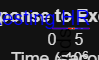


%plot

figure;

plot(time, HR, 'r', 'LineWidth', 2); hold on; % heart rate curve

xline(texercise, '--k', 'Exercise Ends'); % mark transition

yline(HRrest, '--b', 'Resting HR'); % baseline reference

xlabel("Time (seconds)");
ylabel("Heart Rate (bpm)");
title("Heart Rate Response to Exercise and Recovery");
grid on;


% LOGIC INSIGHT 

if HRfinal - HRrest < 5
    fprintf("Good recovery: heart rate returned close to baseline.\n");
else
    fprintf("Slow recovery: elevated heart rate persists.\n");
end

Good recovery: heart rate returned close to baseline.



% EXPORT DATA 
data = table(time', HR', ...
    'VariableNames', {'Time','HeartRate'});

writetable(data, "heartratesim.csv");

fprintf("\nData exported to heartratesim.csv\n");


Data exported to heartratesim.csv



%INTERPRETATION 

fprintf("\n INTERPRETATION \n");


===== INTERPRETATION =====


fprintf("Heart rate rises exponentially during exercise and decays during recovery.\n");

Heart rate rises exponentially during exercise and decays during recovery.


fprintf("Higher recovery constant = faster return to baseline.\n");

Higher recovery constant = faster return to baseline.


fprintf("Lower recovery constant = cardiovascular fatigue or slower recovery.\n");

Lower recovery constant = cardiovascular fatigue or slower recovery.


%{
Reflection After Completing the Project:
    - What did you learn?
    - What could be done differently?
    - Rate the project (1 - 10) 
      (1 - represents simple and 10 represents difficult) 
      This rating should reflect the level of complexity and challenge experienced.
      Factors influencing this rating should include the unfamiliarity of concepts,
      the level of critical thinking required,
      and the degree of effort needed to complete the project successfully.
%}
